# Time Domain Optimization - Regular Wave

## Define all shared variables

clc; clear;

% Run Read_AQWA and process_hydro
hydro = struct();
hydro = Read_AQWA2(hydro,'BEMData/FullScale/ANALYSIS.ah1','BEMData/FullScale/ANALYSIS.lis');

% Wave Data 
T_wave = 5;
f_wave = 1/T_wave;
w_wave = f_wave*(2*pi);
h_wave = 1.5;
t_ramp = T_wave*60;
BEM = process_hydro(hydro,T_wave);

% WaveData struct for regular waves 
waveData = struct();

waveData.h_wave = h_wave;
waveData.w_wave = w_wave;
waveData.t_ramp = t_ramp;

% Body
load("bodies/body.mat")

% Mass ratio
mu = 0.03;

m1 = body.m1;
m = (m1*mu)/3;

body.m = m;

% Tuned Parameters
k = 80000;
c = 190;
k_i =3863;
b = 2694;

tmd_TMD_03 = [85320 592];
tmd_TID_03 = [86554 29 395 516];

tmd_TMD_03_SS1 = [223132 729];
tmd_TID_03_SS1 = [222016 550 652 256];

% Length of simulation
fs = 10;
duration = 1000;
N = fs*duration;
t = 0:1/fs:duration;

## Set up optimization

k_lb = 210000; k_ub = 240000;
c_lb = 1; c_ub = 5000;
c_lb_i = 1; c_ub_i = 1000;
k_i_lb = 10; k_i_ub = 1000;
b_lb = 10; b_ub = 2000;

lb_TMD = [k_lb,c_lb];
ub_TMD = [k_ub,c_ub];

lb_TID = [k_lb,c_lb_i,k_i_lb,b_lb];
ub_TID = [k_ub,c_ub_i,k_i_ub,b_ub];

## Set up initial conditions - heave

r0_noPTO = [0 0 deg2rad(0)];
v0_noPTO = [0 0 0];
y0_noPTO = [r0_noPTO v0_noPTO];

r0_TMD = [0 0 deg2rad(0) body.L2_0 body.L3_0 body.L4_0];
v0_TMD = [0 0 0 0 0 0];
y0_TMD = [r0_TMD v0_TMD];

r0_TID = [0 0 deg2rad(0) body.L2_0 body.L3_0 body.L4_0 body.L5_0 body.L6_0 body.L7_0];
v0_TID = [0 0 0 0 0 0 0 0 0];
y0_TID = [r0_TID v0_TID];

## Run optimization - heave



Iter     Func-count       f(x)      MeshSize     Method
    0           1     0.00417947             1      
    1           2     0.00412205             2     Successful Poll
    2           3     0.00407718             4     Successful Poll
    3           5     0.00407718             2     Refine Mesh
    4           6     0.00407718             1     Refine Mesh
    5           8     0.00407718           0.5     Refine Mesh
    6          10     0.00407718          0.25     Refine Mesh
    7          11     0.00407699           0.5     Successful Poll
    8          13     0.00407699          0.25     Refine Mesh
    9          13     0.00407699         0.125     Refine Mesh
   10          15     0.00407697          0.25     Successful Poll
   11          16     0.00407697         0.125     Refine Mesh
   12          16     0.00407697        0.0625     Refine Mesh
   13          18     0.00407693         0.125     Successful Poll
   14          20     0.00407693        0.0625    

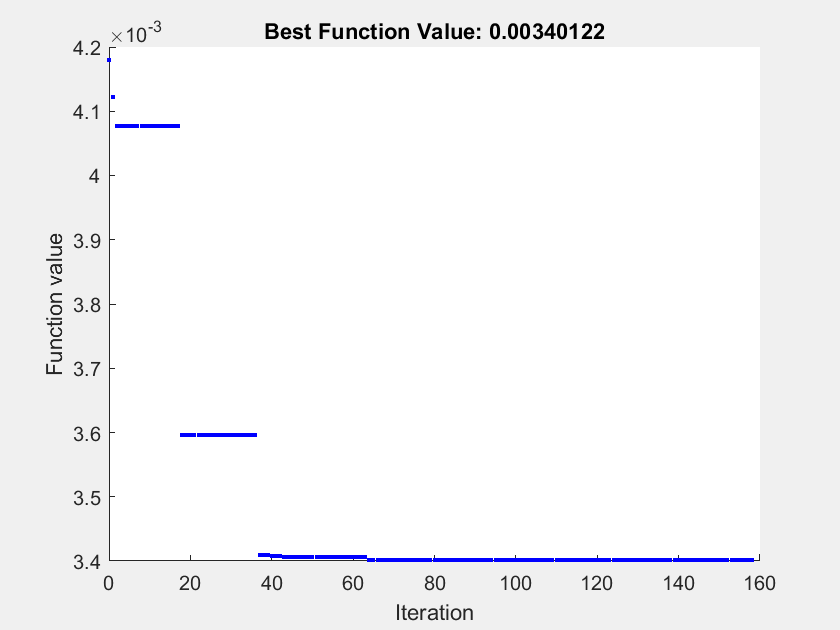

options_p = optimoptions('patternsearch','Display','iter','PlotFcn',@psplotbestf,'MeshTolerance',1e-6,'MaxIterations',2400,'Cache','on');
options_f = optimoptions('fmincon','Display','iter','PlotFcn','optimplotx','OptimalityTolerance',1e-7);

f_TMD = @(tmd) objfun_TD_REG(t,body,BEM,y0_TMD,tmd,'TMD','heave',waveData);
[tmd_opt, fval_TMD] = patternsearch(f_TMD,tmd_TMD_03_SS1,[],[],[],[],lb_TMD,ub_TMD,[],options_p);



Iter     Func-count       f(x)      MeshSize     Method
    0           1     0.00391816             1      
    1           3     0.00377849             2     Successful Poll
    2           4     0.00377579             4     Successful Poll
    3           6     0.00357869             8     Successful Poll
    4           9     0.00355548            16     Successful Poll
    5           9     0.00355548             8     Refine Mesh
    6          11     0.00355548             4     Refine Mesh
    7          12       0.003536             8     Successful Poll
    8          15       0.003536             4     Refine Mesh
    9          18       0.003536             2     Refine Mesh
   10          21      0.0035358             4     Successful Poll
   11          25      0.0035358             2     Refine Mesh
   12          28     0.00349242             4     Successful Poll
   13          29     0.00345787             8     Successful Poll
   14          32     0.00345787      

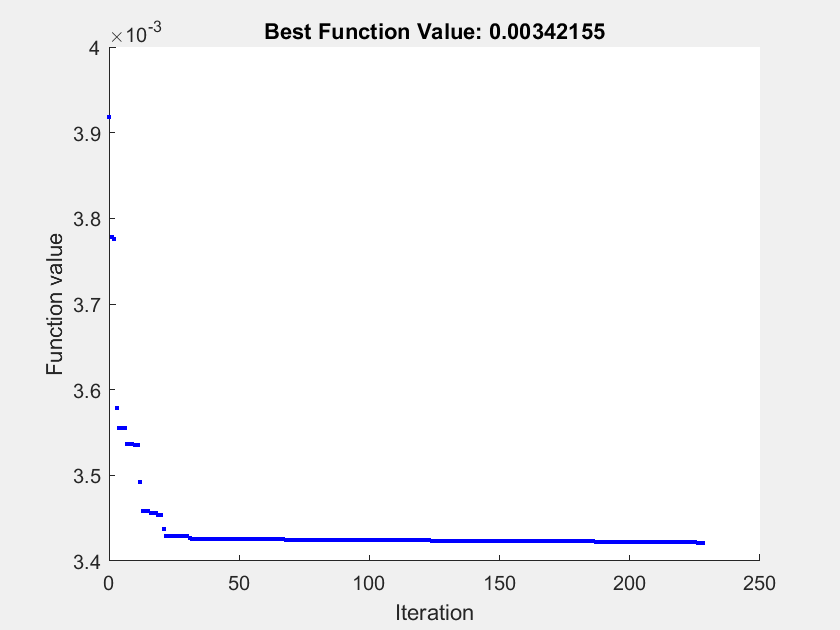


f_TID = @(tmd) objfun_TD_REG(t,body,BEM,y0_TID,tmd,'TID','heave',waveData);
[tid_opt, fval_TID] = patternsearch(f_TID,tmd_TID_03_SS1,[],[],[],[],lb_TID,ub_TID,[],options_p);

## Run studies - heave

fs = 10;
duration = 5000;
N = fs*duration;
t = 0:1/fs:duration;

[t, x_noPTO_regular] = run_dynamic_study(t,body,BEM,y0_noPTO,'PTO','No PTO','waveType','Regular','waveData',waveData);
[t, x_tmd_regular] = run_dynamic_study(t,body,BEM,y0_TMD,tmd_TMD_03_SS1,'PTO','TMD','waveType','Regular','waveData',waveData);
[t, x_tid_regular] = run_dynamic_study(t,body,BEM,y0_TID,tmd_TID_03_SS1,'PTO','TID','waveType','Regular','waveData',waveData);

## Calculate RMS values

RMS_baseline_heave = sqrt(mean(x_noPTO_regular(:,3).^2))*(180/pi);
RMS_tmd_heave = sqrt(mean(x_tmd_regular(:,3).^2))*(180/pi);
RMS_tid_heave = sqrt(mean(x_tid_regular(:,3).^2))*(180/pi);

PR_tmd_heave = (RMS_baseline_heave-RMS_tmd_heave)*100/RMS_baseline_heave;
PR_tid_heave = (RMS_baseline_heave-RMS_tid_heave)*100/RMS_baseline_heave;

## Plot results - heave

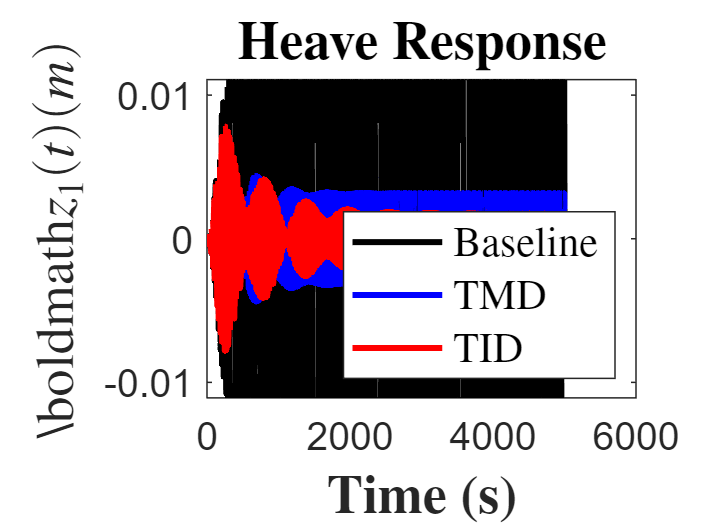

close all;
figure(1)
plot(t,x_noPTO_regular(:,2),'k','LineWidth',2)
hold on
plot(t,x_tmd_regular(:,2),'b','LineWidth',2)
plot(t,x_tid_regular(:,2),'r','LineWidth',2)
% yticks([-0.05 -0.025 0 0.025 0.05])
set(gca,'FontSize',13)
title('\textbf{Heave Response}','Interpreter','latex',"FontSize",18')
xlabel('\textbf{Time (s)}','Interpreter','latex',"FontSize",18)
ylabel('\boldmath$z_{1}(t) (m)$','Interpreter','latex',"FontSize",18)
legend('Baseline', 'TMD','TID','Location','southeast','interpreter', 'latex',"FontSize",14)
hold off

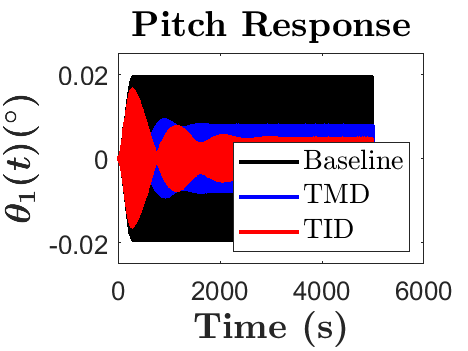


figure(2)
plot(t,x_noPTO_regular(:,3)*(180/pi),'k','LineWidth',2)
hold on
plot(t,x_tmd_regular(:,3)*(180/pi),'b','LineWidth',2)
plot(t,x_tid_regular(:,3)*(180/pi),'r','LineWidth',2)
% xlim([0 800])
ylim([-0.025 0.025])
set(gca,'FontSize',13)
title('\textbf{Pitch Response}','Interpreter','latex',"FontSize",18')
xlabel('\textbf{Time (s)}','Interpreter','latex',"FontSize",18)
ylabel('\boldmath$\theta_{1}(t) (^{\circ})$','Interpreter','latex',"FontSize",18)
legend('Baseline', 'TMD','TID','Location','southeast','interpreter', 'latex',"FontSize",14)
hold off

## Fourier transform

warning off;

SS_i = 3000*fs;

[f_baseline_heave,S_baseline_heave] = calculate_fourier_transform(x_noPTO_regular(SS_i:end,2),fs);
[f_baseline_pitch,S_baseline_pitch] = calculate_fourier_transform(x_noPTO_regular(SS_i:end,3),fs);

[f_tmd_heave,S_tmd_heave] = calculate_fourier_transform(x_tmd_regular(SS_i:end,2),fs);
[f_tmd_pitch,S_tmd_pitch] = calculate_fourier_transform(x_tmd_regular(SS_i:end,3),fs);

[f_tid_heave,S_tid_heave] = calculate_fourier_transform(x_tid_regular(SS_i:end,2),fs);
[f_tid_pitch,S_tid_pitch] = calculate_fourier_transform(x_tid_regular(SS_i:end,3),fs);
warning on;

## Plot results - frequency

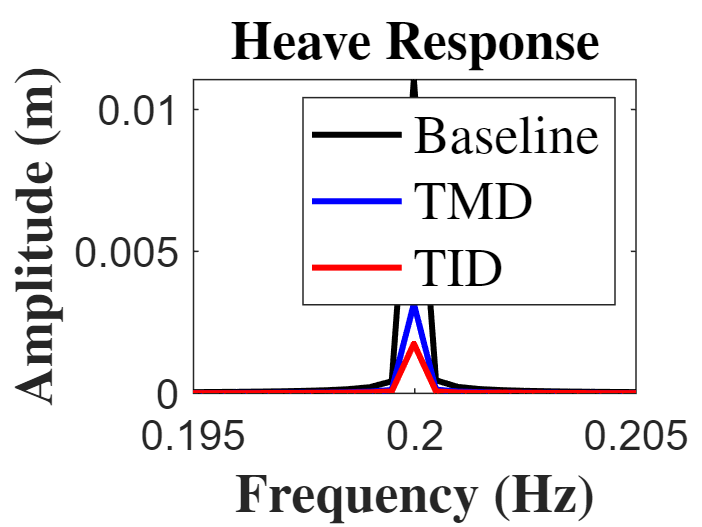

close all;

figure(3)
plot(f_baseline_heave,S_baseline_heave,'Color','k','LineWidth',2)
hold on
plot(f_baseline_heave,S_tmd_heave,'Color','b','LineWidth',2)
plot(f_baseline_heave,S_tid_heave,'Color','r','LineWidth',2)
set(gca,"FontSize",14)
title('\textbf{Heave Response}','Interpreter','latex',"FontSize",18)
xlabel('\textbf{Frequency (Hz)}','Interpreter','latex',"FontSize",18)
ylabel('\textbf{Amplitude (m)}','Interpreter','latex',"FontSize",18)
legend('Baseline','TMD','TID','Location','northeast','Interpreter','latex','FontSize',18)
xlim([0.195 0.205])
% ylim([0 0.05])
hold off

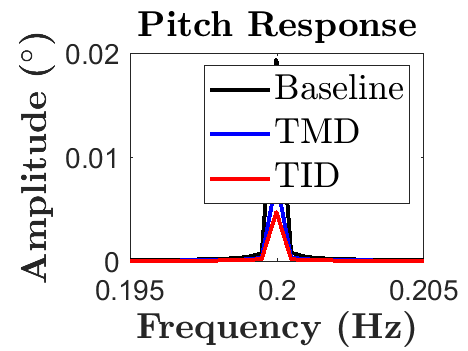


figure(4)
plot(f_baseline_pitch,S_baseline_pitch*(180/pi),'Color','k','LineWidth',2)
hold on
plot(f_baseline_pitch,S_tmd_pitch*(180/pi),'Color','b','LineWidth',2)
plot(f_baseline_pitch,S_tid_pitch*(180/pi),'Color','r','LineWidth',2)
set(gca,"FontSize",14)
title('\textbf{Pitch Response}','Interpreter','latex',"FontSize",18)
xlabel('\textbf{Frequency (Hz)}','Interpreter','latex',"FontSize",18)
ylabel('\textbf{Amplitude} \boldmath$(^{\circ})$','Interpreter','latex',"FontSize",18)
legend('Baseline','TMD','TID','Location','northeast','Interpreter','latex','FontSize',18)
xlim([0.195 0.205])
% ylim([0 0.15])
hold off